***matlab图像绘制***

**(1)基本绘图函数:**

plot函数:

例1:

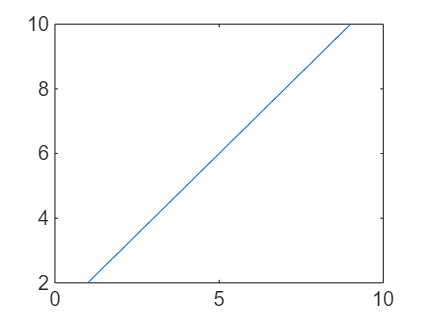

x=[1:9];
y=[2:10];
plot(x,y);%只有点,不是整个图像都显示出来

例2:

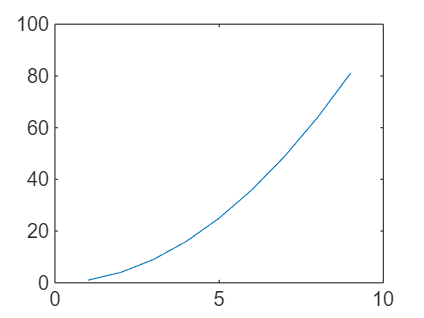

x=[1:9];
y=x.^2;
plot(x,y)

例3:(复数)

x=[1:9];
y=[0.1:0.2:1.7];
X=x+y*i

X =                           1 +                   0.1i                          2 +                   0.3i                          3 +                   0.5i                          4 +                   0.7i                          5 +                   0.9i                          6 +                   1.1i                          7 +                   1.3i                          8 +                   1.5i                          9 +                   1.7i


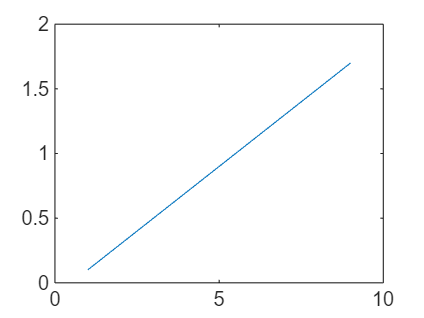

plot(X)

例4:当x,y为矩阵时

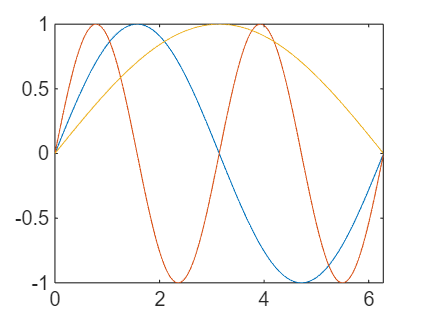

t=0:0.01:2*pi;
t=t.';
x=[t,t,t];
y=[sin(t),sin(2*t),sin(0.5*t)];
plot(x,y)

例5:绘制多条函数:

linspace函数:(生成线性间距的向量)

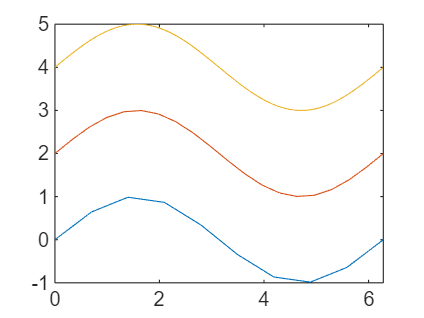

x1=linspace(0,2*pi,10);
x2=linspace(0,2*pi,20);
x3=linspace(0,2*pi,200);
y1=sin(x1);
y2=sin(x2)+2;
y3=sin(x3)+4;
plot(x1,y1,x2,y2,x3,y3);

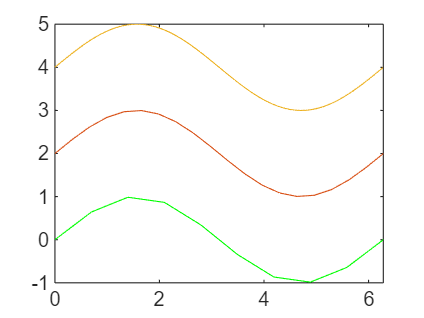

%可以将多条函数放在同一个图像中
plot(x1,y1,'g',x2,y2,x3,y3)%折线

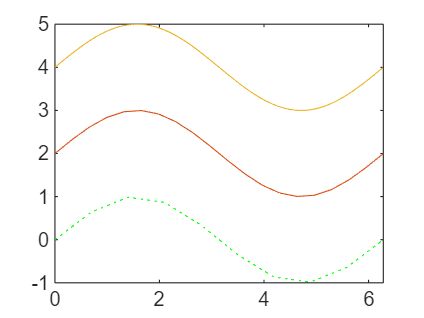

plot(x1,y1,':g',x2,y2,x3,y3)%只有点

%添加颜色

基本绘图函数:

fplot函数:平滑差值

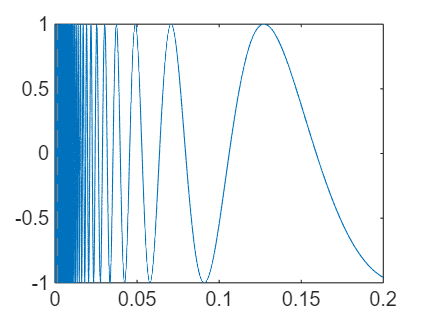

fplot(@(x)sin(1./x),[0,0.2])

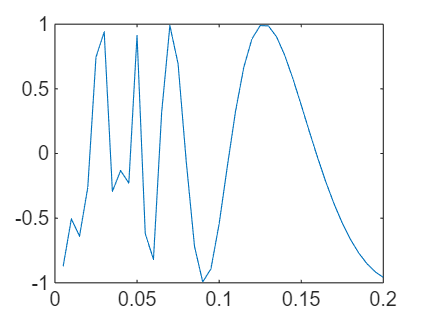

x=[0:0.005:0.2];
y=sin(1./x);
plot(x,y)

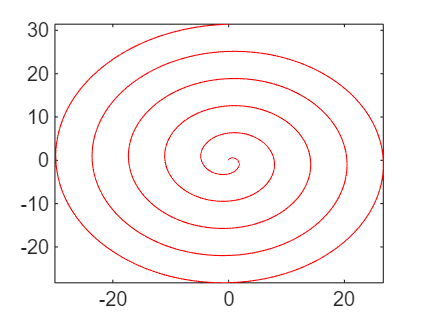

fplot(@(t) t*sin(t),@(t) t*cos(t),[0,10*pi],'-r')

%'r'红色线条

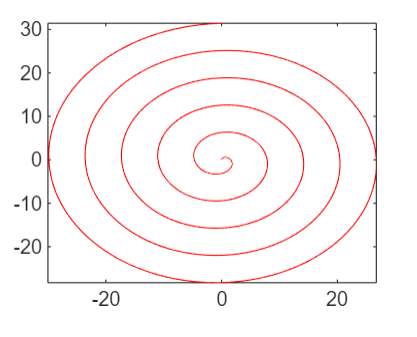

**(2)对数坐标图**

semilogx函数:x轴使用以10为底的对数刻度,y轴线性刻度

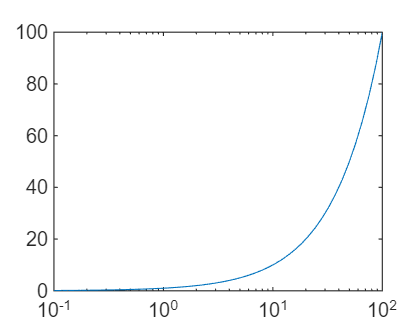

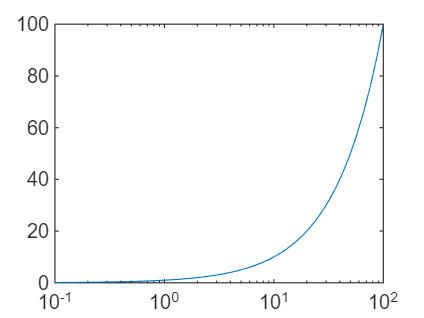

x=logspace(-1,2);
y=x;
semilogx(x,y);

**(3)极坐标图**

polarplot:

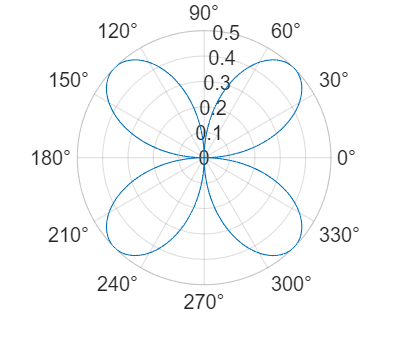

theta=0:0.01:2*pi;
rho=sin(theta).*cos(theta)

rho =                          0       0.00999933334666654        0.0199946670933171        0.0299820032397223        0.0399573469845863        0.0499167083234141        0.0598561036444597        0.0697715573221182         0.079659103307123        0.0895147867129121        0.0993346653975306         0.109114811540435         0.118851313213567         0.128540275946078         0.138177824282057          0.14776010333067         0.157283280308059         0.166743546070407         0.176137116637545         0.185460234706491         0.194709171154325         0.203880226529785            0.212969732533          0.22197405348276         0.230889587770741         0.239712769302102         0.248440068921868         0.257067995826557         0.265593098960442         0.274011968395937         0.282321236697518         0.290517580268653         0.298597720681196         0.306558425986717         0.314396512009234         0.322108843618846         0.329692335985737         0.337143955814073      

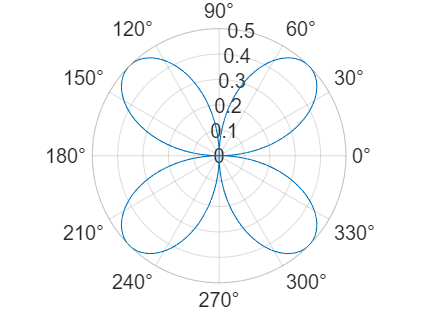

polarplot(theta,rho)

**(4)条形图**

bar(y)函数:

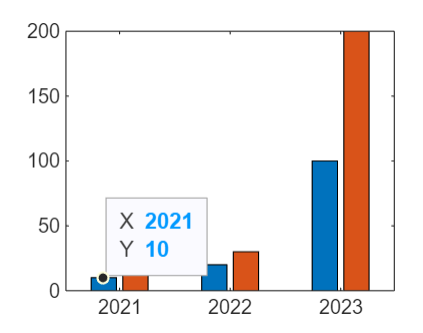

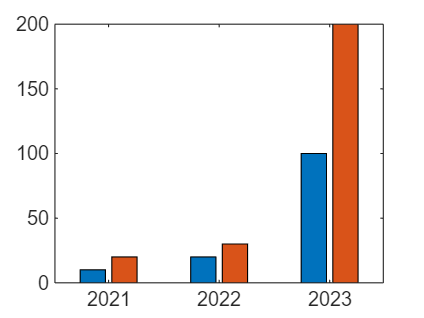

x=[2021,2022,2023];
y=[10,20;20,30;100,200];
bar(x,y);

**(5)直方图**

histogram函数:

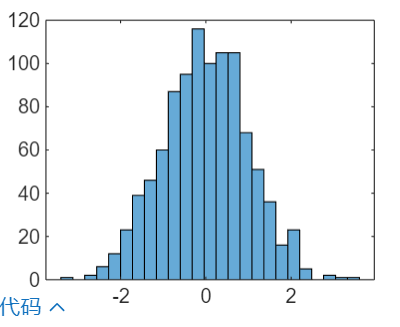

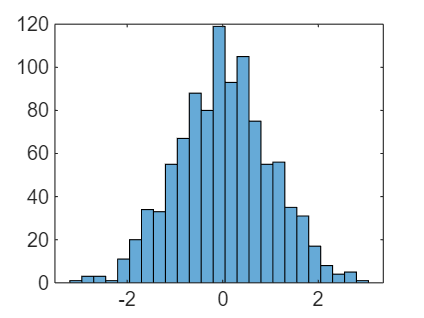

x=randn(1000,1);
nbins=25;%格的个数
histogram(x,nbins);

counts=h.Values

无法解析名称 'h.Values'。

**(6)面积类图形**

pie(X)饼状图函数:

如果sum(X)<=1,X中的值直接指定饼状图扇形区域的面积

若sum(X)<1,则仅绘制部分饼状图

若sum(X)>1,则pie函数通过归一化来确定每个扇形区的面积

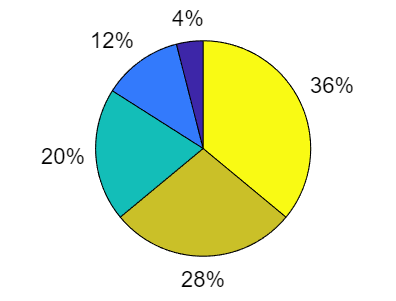

x=linspace(1,9,5)

x =      1     3     5     7     9


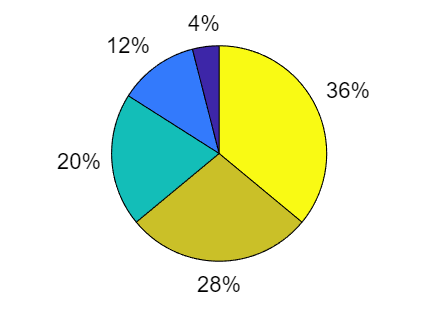

pie(x)

**(7)散点图**

scatter函数:

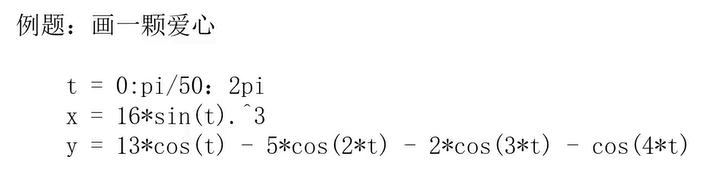

t=0:pi/50:2*pi;
x=16*sin(t).^3

x =                          0       0.00396097600886199        0.0315005920329391         0.105268595112709         0.246090222263503         0.472135954999579         0.798186422352058          1.23501885426635           1.7889371755075          2.46146273449005          3.24919696232906          4.14386115680882          5.13251230004111          6.19792757006218          7.31914421690261          8.47213595499958          9.63060217176696          10.7668422386436          11.8526841782517          12.8604349969193          13.7638192047117          14.5388724432292          15.1647587107523          15.6244823593267           15.905469744054                        16           15.905469744054          15.6244823593267          15.1647587107523          14.5388724432292          13.7638192047117          12.8604349969193          11.8526841782516          10.7668422386436          9.63060217176696          8.47213595499958          7.31914421690261          6.19792757006218        

y=13*cos(t)-5*cos(2*t)-2*cos(3*t)-cos(4*t)

y =                          5          5.08061630040913          5.31871565962469          5.70322735160625          6.21628364463107          6.83406224100236          7.52790207678075          8.26563327357082          9.01305111818169          9.73545703057813          10.3991869381244          10.9730494172483          11.4296022396436          11.7462061615856          11.9058082856376          11.8974232786421            11.71629818493          11.3637644866389          10.8467983759324          10.1773259074106            9.371322893124          8.44776935024081          7.42752448159226           6.3321902673046          5.18302972849628                         4          2.80095096239123          1.60102798389398         0.412303122447429        -0.756356139760169         -1.89918693812442         -3.01322067225511         -4.09779584927404         -5.15393795371879         -6.18365728978186         -7.18921934614277         -8.17244216800382         -9.13407156366349        

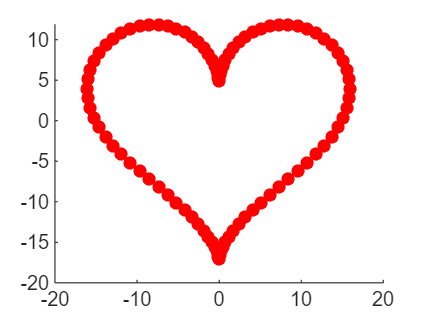

scatter(x,y,'red',"filled")

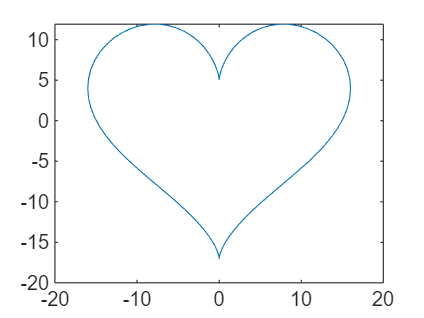

plot(x,y)

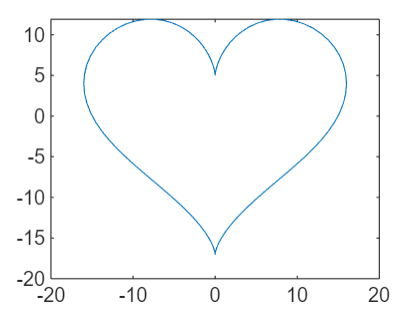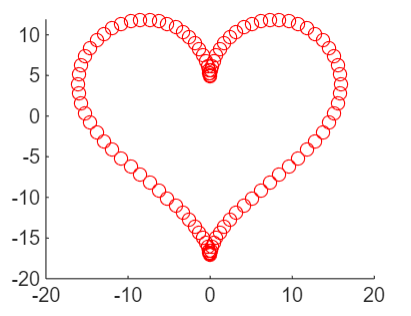

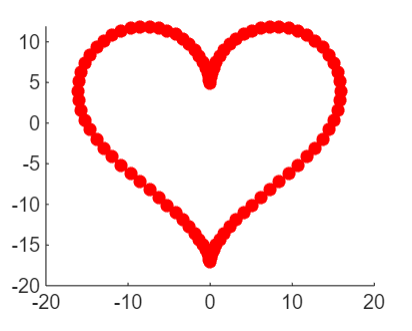

**(8)矢量类图形**

quiver函数:

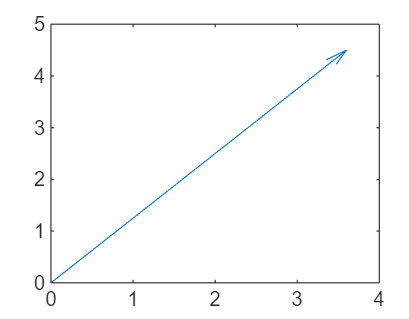

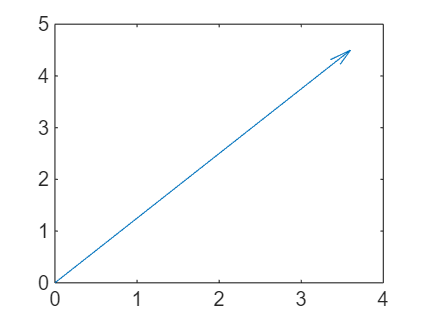

A=[4,5];
quiver(0,0,A(1),A(2));

示例1:基本用法

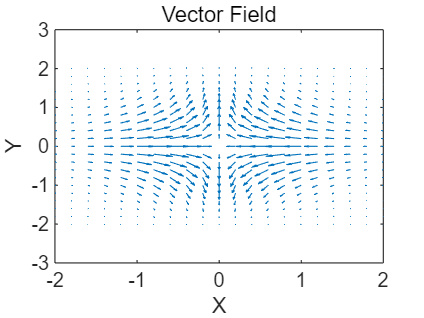

[x, y] = meshgrid(-2:0.2:2, -2:0.2:2);
u = -x .* exp(-x.^2 - y.^2);
v = y .* exp(-x.^2 - y.^2);
figure;
quiver(x, y, u, v);
title('Vector Field');%图像命名
xlabel('X');%x轴命名
ylabel('Y');%y轴命名

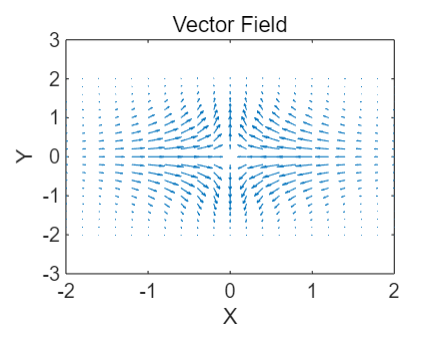

示例 2：指定颜色和线型

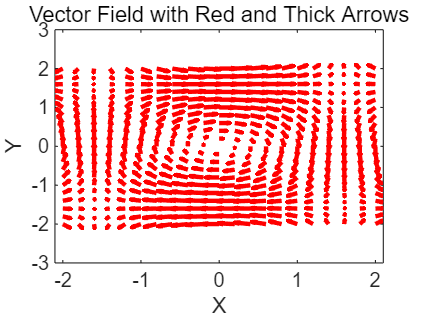

[x, y] = meshgrid(-2:0.2:2, -2:0.2:2);
u = cos(x) .* sin(y);
v = -sin(x) .* cos(y);
figure;
quiver(x, y, u, v, 'r', 'LineWidth', 2);
title('Vector Field with Red and Thick Arrows');
xlabel('X');
ylabel('Y');

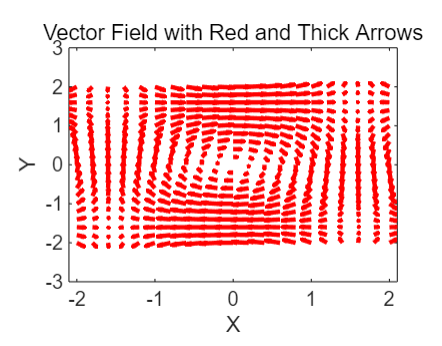

示例 3：自动缩放箭头大小

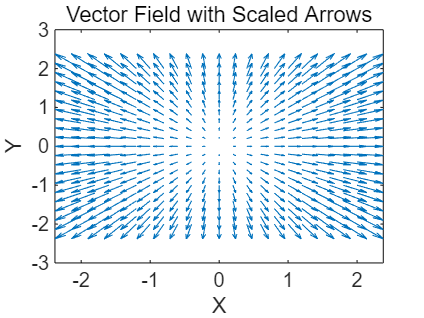

[x, y] = meshgrid(-2:0.2:2, -2:0.2:2);
u = x;
v = y;
figure;
quiver(x, y, u, v, 2);
title('Vector Field with Scaled Arrows');
xlabel('X');
ylabel('Y');

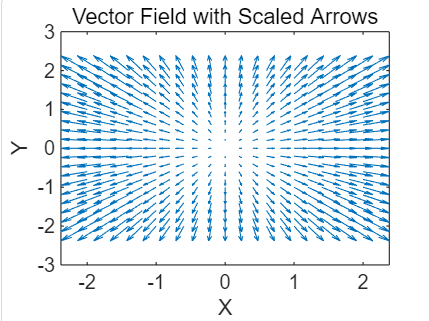

**2.图形属性的设置**

(1)线型:

"-":实线

"--"虚线

":"点线

"-."点划线

(2)标记:

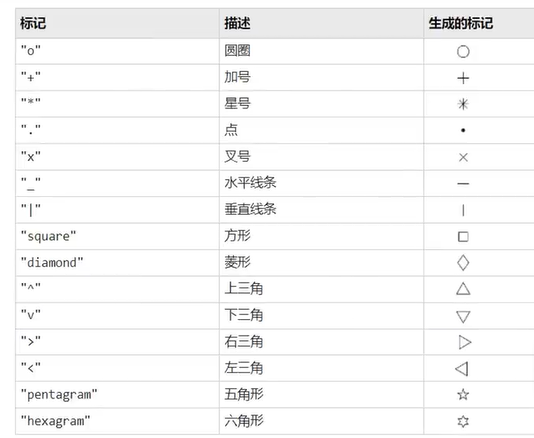

(3)颜色

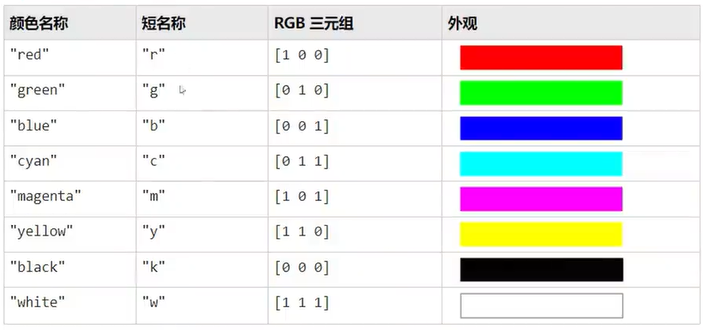

(4)图形属性设置:

(5)坐标控制:

axis函数:指定当前坐标区的范围

grid函数:给坐标系加网格和边框(如果没有grid默认无网格线)

例子:

x=linspace(0,2*pi,200);
y=[sin(x);sin(2*x);sin(0.5*x)];
plot(x,y)
axis([0,6.5,-1.5,1.5]);
title('三个正弦函数曲线','FontSize',24)
xlabel('x');
ylabel('Y');
text(2.5,sin(2.5),'sin(x)');
text(2.5,sin(2*2.5),'sin(2*x)');
legend('sin(x)','sin(2*x)','sin(0.5*x)');


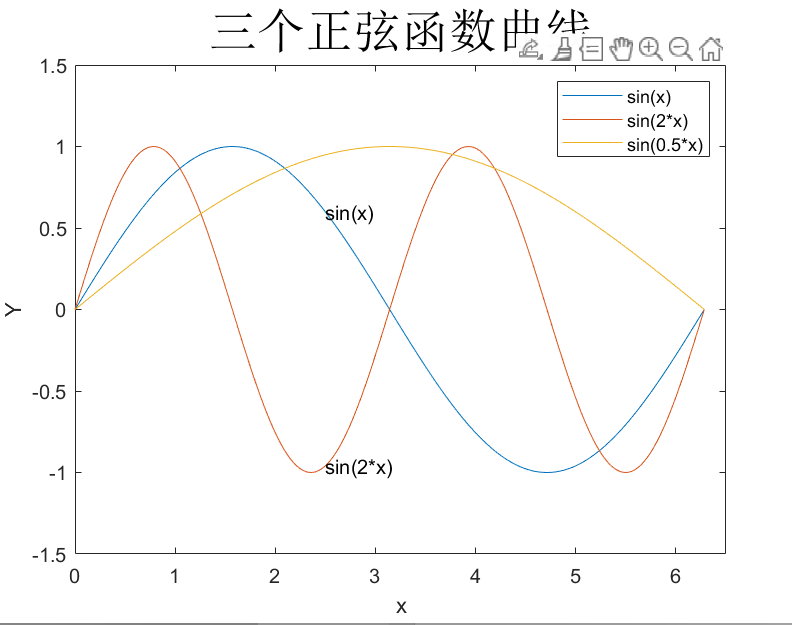

(6)图形属性保持

hold函数:

例子:画同心圆

t=linspace(0,2*pi,200);
x=sin(t);
y=cos(t);
plot(x,y,'b');
axis equal
hold on
x1=2*sin(t);
y2=2*cos(t);
plot(x1,y2,'r');

例题;

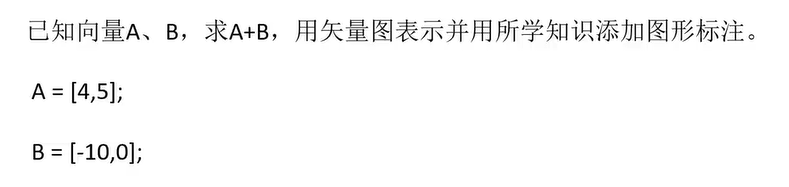

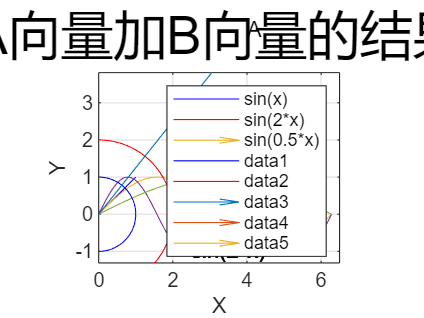

clear;
clc;
A=[4,5];
B=[-10,0];
C=A+B;
hold on
quiver(0,0,A(1),A(2));
quiver(0,0,C(1),C(2));
quiver(0,0,B(1),B(2));
title('A向量加B向量的结果');
xlabel('X');
ylabel('Y');
text(A(1),A(2),'A');
text(B(1),B(2),'B');
text(C(1),C(2),'C');
grid on